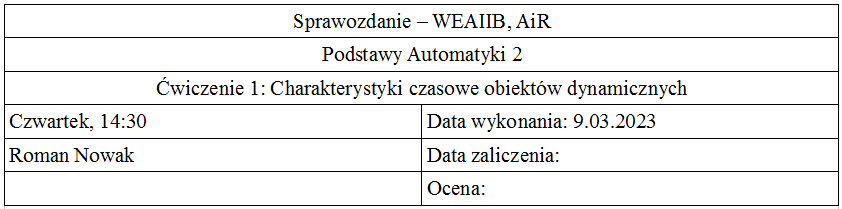

Cel cwiczenia: 

Celem ćwiczenia jest zapoznanie się z charakterystykami czasowymi ( odpowiedziami czasowymi obiektu na

określone wymuszenie ) podstawowych obiektów dynamicznych. Ćwiczenie zostanie wykonane symulacyjnie z

wykorzystaniem pakietu MATLAB. W czasie ćwiczenia będą badane odpowiedzi obiektów na następujące typy

wymuszeń:

• skok jednostkowy ( charakterystyki skokowe )

• delta Diraca ( charakterystyki impulsowe )

Wstęp teoretyczny - definicje:

Charakterystyka skokowa - odpowiedź układu na ktorego wejście podano sygnal skokowy opisany rownaniem:

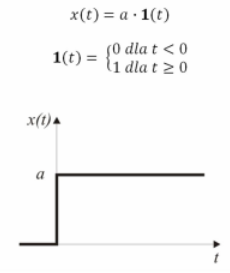

Charakterzstzka impulsowa - odpowiedz ukladu na ktorego wejscie podanz sygnał w postaci impulsu diraca opisanego rownaniem:

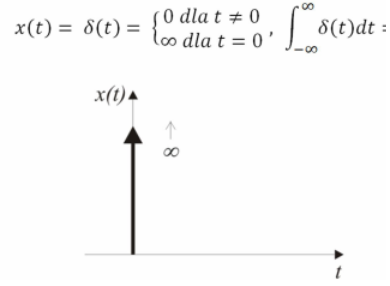

Transmitancja operatorowa - stosunek transformaty Laplace’a sygnału wyjściowego do transformaty Laplace’a sygnału wejściowego układu przy zerowych warunkach początkowych.

1.Obiekt inercyjny pierwszego rzędu

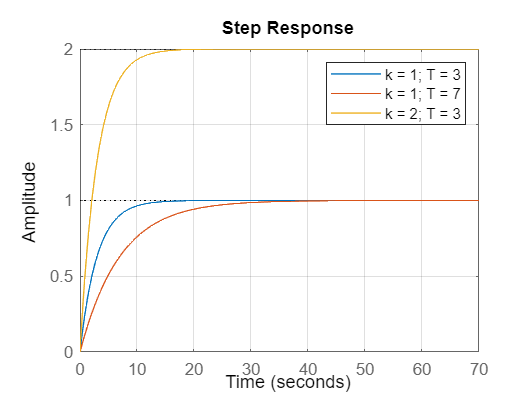

clear;

figure; hold on;
k = 1; T = 3;
licz = [0 k]; mian = [T, 1];
step(licz, mian)

k = 1; T = 7;
licz = [0 k]; mian = [T, 1];
step(licz, mian)

k = 2; T = 3;
licz = [0 k]; mian = [T, 1];
step(licz, mian)
legend("k = 1; T = 3", "k = 1; T = 7", "k = 2; T = 3");
grid on; hold off;

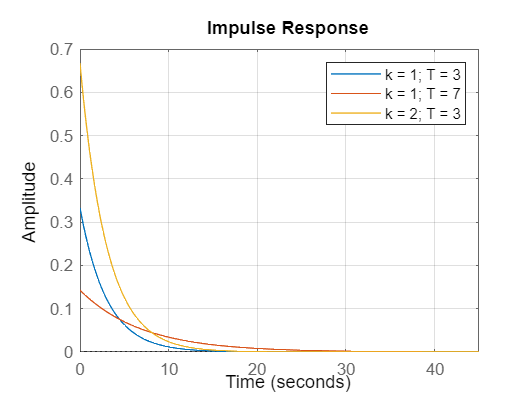


figure; hold on;
k = 1; T = 3;
licz = [0 k]; mian = [T, 1];
impulse(licz, mian)

k = 1; T = 7;
licz = [0 k]; mian = [T, 1];
impulse(licz, mian)

k = 2; T = 3;
licz = [0 k]; mian = [T, 1];
impulse(licz, mian)
legend("k = 1; T = 3", "k = 1; T = 7", "k = 2; T = 3");
grid on; hold off;

2. Obiekt inercyjny drugiego rzędu

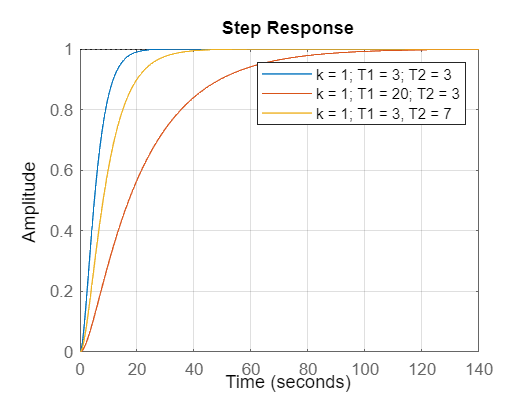

clear; figure; hold on;
k = 1; T1 = 3; T2 = 3;
licz = [0 0 k]; mian = [T1 * T2, T1 + T2, 1];
step(licz, mian)

k = 1; T1 = 20; T2 = 3;
licz = [0 0 k]; mian = [T1 * T2, T1 + T2, 1];
step(licz, mian)

k = 1; T1 = 3; T2 = 7;
licz = [0 0 k]; mian = [T1 * T2, T1 + T2, 1];
step(licz, mian)
legend("k = 1; T1 = 3; T2 = 3", "k = 1; T1 = 20; T2 = 3", "k = 1; T1 = 3, T2 = 7");
grid on; hold off;

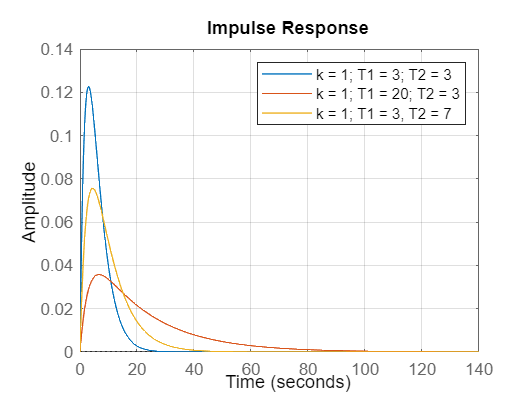


figure; hold on;
k = 1; T1 = 3; T2 = 3;
licz = [0 0 k]; mian = [T1 * T2, T1 + T2, 1];
impulse(licz, mian)

k = 1; T1 = 20; T2 = 3;
licz = [0 0 k]; mian = [T1 * T2, T1 + T2, 1];
impulse(licz, mian)

k = 1; T1 = 3; T2 = 7;
licz = [0 0 k]; mian = [T1 * T2, T1 + T2, 1];
impulse(licz, mian)
legend("k = 1; T1 = 3; T2 = 3", "k = 1; T1 = 20; T2 = 3", "k = 1; T1 = 3, T2 = 7");
grid on; hold off;

3. obiekt oscylacyjny II rzędu

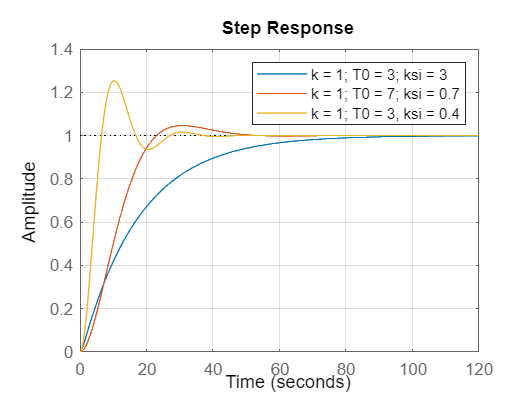

clear; figure; hold on;
k = 1; T0 = 3; ksi = 3;
licz = [0 0 k]; mian = [T0^2, 2 * ksi * T0, 1];
step(licz, mian)

k = 1; T0 = 7; ksi = 0.7;
licz = [0 0 k]; mian = [T0^2, 2 * ksi * T0, 1];
step(licz, mian)

k = 1; T0 = 3; ksi = 0.4;
licz = [0 0 k]; mian = [T0^2, 2 * ksi * T0, 1];
step(licz, mian)
legend("k = 1; T0 = 3; ksi = 3", "k = 1; T0 = 7; ksi = 0.7", "k = 1; T0 = 3, ksi = 0.4");
grid on; hold off;

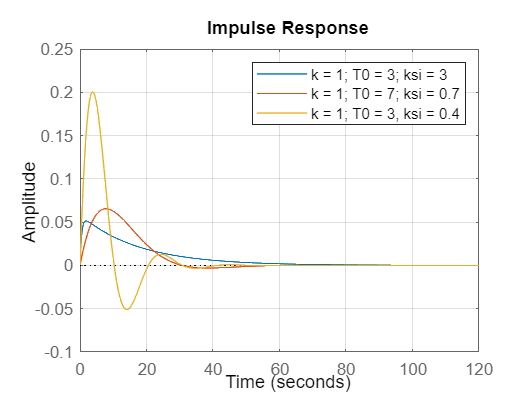


figure; hold on;
k = 1; T0 = 3; ksi = 3;
licz = [0 0 k]; mian = [T0^2, 2 * ksi * T0, 1];
impulse(licz, mian)

k = 1; T0 = 7; ksi = 0.7;
licz = [0 0 k]; mian = [T0^2, 2 * ksi * T0, 1];
impulse(licz, mian)

k = 1; T0 = 3; ksi = 0.4;
licz = [0 0 k]; mian = [T0^2, 2 * ksi * T0, 1];
impulse(licz, mian)
legend("k = 1; T0 = 3; ksi = 3", "k = 1; T0 = 7; ksi = 0.7", "k = 1; T0 = 3, ksi = 0.4");
grid on; hold off;

4. obiekt całkujący z inercją I rzędu o transmitancji:

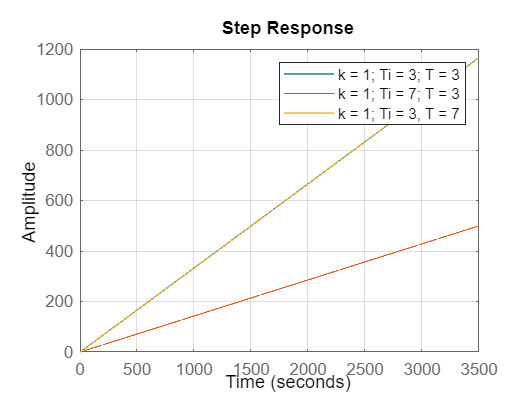

clear; figure; hold on;
k = 1; Ti = 3; T = 3;
licz = [0 0 k]; mian = [Ti * T, Ti, 0];
step(licz, mian)

k = 1; Ti = 7; T = 3;
licz = [0 0 k]; mian = [Ti * T, Ti, 0];
step(licz, mian)

k = 1; Ti = 3; T = 7;
licz = [0 0 k]; mian = [Ti * T, Ti, 0];
step(licz, mian)
legend("k = 1; Ti = 3; T = 3", "k = 1; Ti = 7; T = 3", "k = 1; Ti = 3, T = 7");
grid on; hold off;

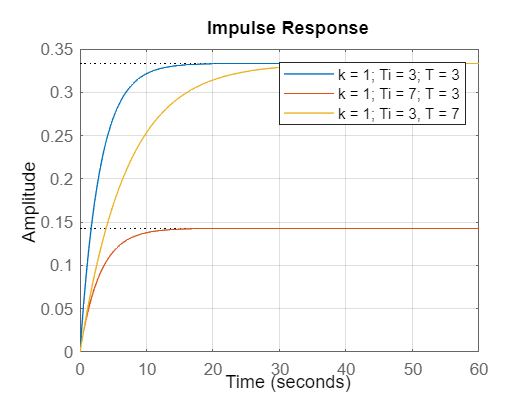


figure; hold on;
k = 1; Ti = 3; T = 3;
licz = [0 0 k]; mian = [Ti * T, Ti, 0];
impulse(licz, mian)

k = 1; Ti = 7; T = 3;
licz = [0 0 k]; mian = [Ti * T, Ti, 0];
impulse(licz, mian)

k = 1; Ti = 3; T = 7;
licz = [0 0 k]; mian = [Ti * T, Ti, 0];
impulse(licz, mian)
legend("k = 1; Ti = 3; T = 3", "k = 1; Ti = 7; T = 3", "k = 1; Ti = 3, T = 7");
grid on; hold off;

5. obiekt różniczkujący rzeczywisty

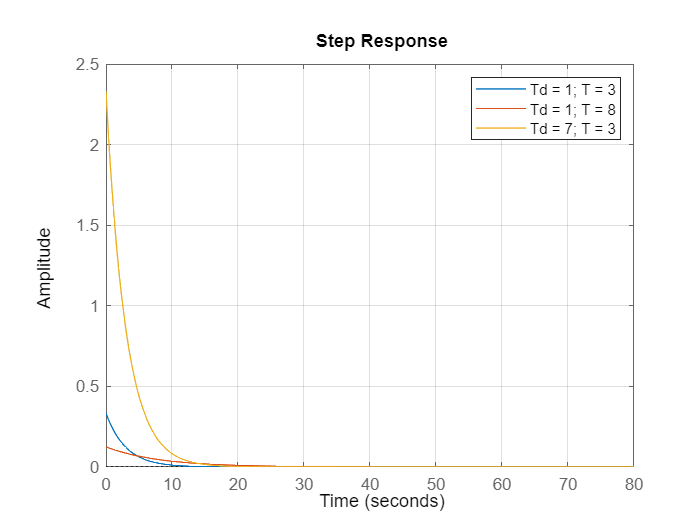

clear; figure; hold on;
Td = 1; T = 3;
licz = [Td 0]; mian = [T, 1];
step(licz, mian)

Td = 1; T = 8;
licz = [Td 0]; mian = [T, 1];
step(licz, mian)

Td = 7; T = 3;
licz = [Td 0]; mian = [T, 1];
step(licz, mian)
legend("Td = 1; T = 3", "Td = 1; T = 8", "Td = 7; T = 3");
grid on; hold off;

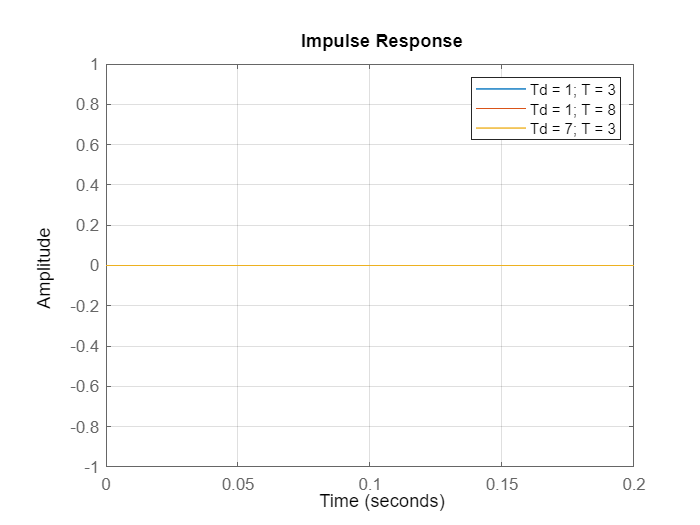


figure; hold on;
Td = 1; T = 3;
licz = [Td 0]; mian = [T, 0];
impulse(licz, mian)

Td = 1; T = 8;
licz = [Td 0]; mian = [T, 0];
impulse(licz, mian)

Td = 7; T = 3;
licz = [Td 0]; mian = [T, 0];
impulse(licz, mian)
legend("Td = 1; T = 3", "Td = 1; T = 8", "Td = 7; T = 3");
grid on; hold off;

6. Obiekt inercyjny I rzędu z opóźnieniem

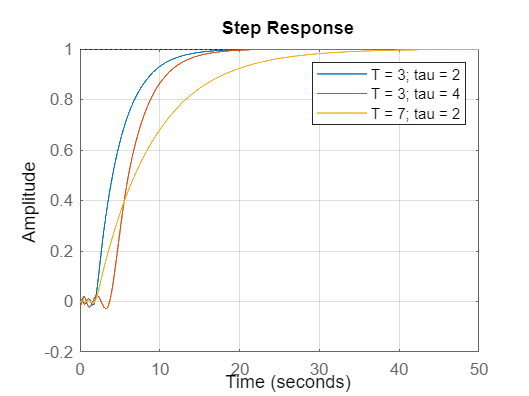

clear;
T = 3; tau = 2;
[licz_op, mian_op] = pade(tau, 5);
licz_iner = [0 1];
mian_iner = [T 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
figure; hold on;
step(licz, mian)

T = 3; tau = 4;
[licz_op, mian_op] = pade(tau, 5);
licz_iner = [0 1];
mian_iner = [T 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
step(licz, mian)

T = 7; tau = 2;
[licz_op, mian_op] = pade(tau, 5);
licz_iner = [0 1];
mian_iner = [T 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
step(licz, mian)
legend("T = 3; tau = 2", "T = 3; tau = 4", "T = 7; tau = 2");
grid on; hold off;

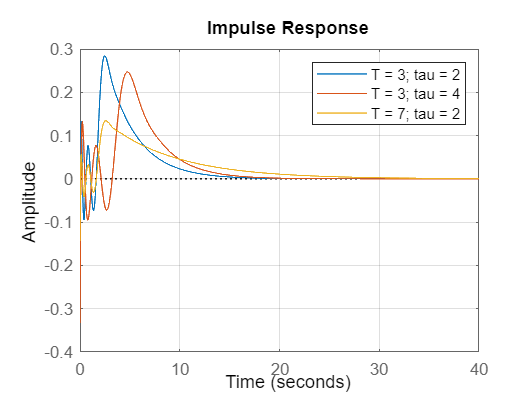


figure; hold on;
T = 3; tau = 2;
[licz_op, mian_op] = pade(tau, 5);
licz_iner = [0 1];
mian_iner = [T 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
impulse(licz, mian)

T = 3; tau = 4;
[licz_op, mian_op] = pade(tau, 5);
licz_iner = [0 1];
mian_iner = [T 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
impulse(licz, mian)

T = 7; tau = 2;
[licz_op, mian_op] = pade(tau, 5);
licz_iner = [0 1];
mian_iner = [T 1];
[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
impulse(licz, mian)
legend("T = 3; tau = 2", "T = 3; tau = 4", "T = 7; tau = 2");
grid on; hold off;

Wnioski:

Ćwiczenie pozwoliło na zapoznanie się odpowiedziami impulsowymi i skokowymi różnego typu obiektów dynamicznych. Przykładowo: odpowiedź skokowa obiektu całkującego dąży liniowo do nieskończoności, odpowiedzi obiektu różniczkującego są stałe, a wprowadzenie do obiektu inercyjnego opóźnienia, powoduje, oprócz późniejszej reakcji układu, pojawienie się oscylacji.

Został zbadany wpływ wartości poszczególnych parametrów każdego obiektu na jego odpowiedzi. Na przykład: parametr T odpowiada za czas ustalenia się odpowiedzi obiektu, a k, za maksymalną wartość, parametr ksi odpowiada za tłumienie pojawiających się na wyjściu oscylacji.